%Load training & test image sets
names = ["amuro", "ange", "chiyuki",... 
    "gabriel", "kaguya", "katsuhira",... 
    "minene", "nagisa", "nao",... 
    "noriko", "ranpo", "sora",... 
    "tenshi", "vivy", "Chizuru",... 
    "Makise", "Haruhi", "Akutagawa",...
    "Anya", "Denji", "Hitagi", "Hori",...
    "Itadori", "Kazehara", "Mashiro",...
    "Nazuna", "Sakura", "Tohsaka",...
    "Futaba", "Hachiman", "Hayasaka",...
    "Ishigami", "Kaede", "Koga",...
    "Mai", "Nodoka", "Sakuta", "Shirogane",...
    "Shoko", "Yui", "Yukino", "Yuuma"];
[test_chars,test_names,train_chars,train_names] = loadImg(names);

%Perform Principal Component Analysis

%Calculate covariance matrix
char_cov = cov(train_chars);

%Calculate eigenvectors of cov matrix
[V, D] = eigs(char_cov, 32);

%train data projection
char_proj = train_chars * V;

%test img projection
test_idx = 21;
test_char = test_chars(test_idx, :);
test_proj = test_char * V;

%find test point with shortest distance from a train point
iter = length(train_names);

iter = 84

min_idx = getClosest(test_proj,char_proj,iter);

min_idx = 63

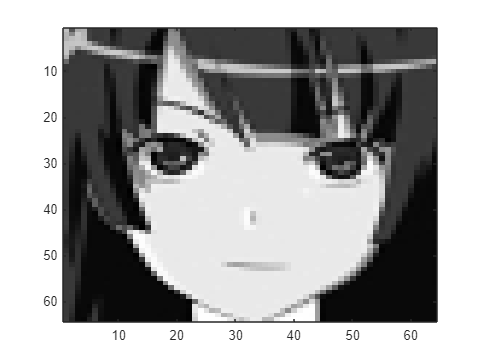


figure()
colormap gray
imagesc(reshape(test_char, [64 64]))

test_names(test_idx)

ans = "Hitagi3"

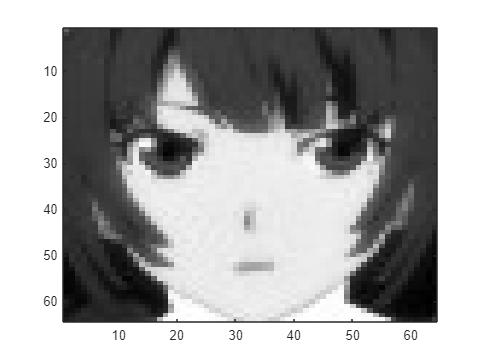

imagesc(reshape(train_chars(min_idx, :), [64 64]))

train_names(min_idx)

ans = "Hitagi2"

%accuracy testing
acc = 0;
wrong = [];
for i=1:length(test_names)
    min_dist_acc = 100000000;
    min_dist_idx_acc = 0;
    test_char_acc = test_chars(i, :);
    test_proj_acc = test_char_acc * V;
    for k = 1:length(train_names)
        temp_char_proj = char_proj(k,:);
        temp_dist = (test_proj_acc - temp_char_proj).^2;
        temp_dist = sum(temp_dist);
        temp_dist = sqrt(temp_dist);
        if temp_dist < min_dist_acc
            min_dist_acc = temp_dist;
            min_dist_idx_acc = k;
        end
    end
    test_name = extractBetween(test_names(i), 1, strlength(test_names(i)) - 1);
    result_name = extractBetween(train_names(min_dist_idx_acc), 1, strlength(train_names(min_dist_idx_acc)) - 1);
    if strcmp(test_name, result_name) 
        acc = acc + 1;
    else
        wrong(end+1) = i;
    end
end
acc/length(test_names)

ans = 0.7262

for i=1:length(wrong)
    test_names(wrong(i));
end

eigenvecs = 1:100;
accs = zeros(1, length(eigenvecs));
for j = eigenvecs
    temp_acc = 0;
    %find eigenvectors of cov matrix
    [V_temp, D_temp] = eigs(char_cov, j);
    
    %projection
    char_proj_temp = train_chars * V_temp;

    %accuracy
    for i=1:length(test_names)
        min_dist_acc = 100000000;
        min_dist_idx_acc = 0;
        test_char_acc = test_chars(i, :);
        test_proj_acc = test_char_acc * V_temp;
        for k = 1:length(train_names)
            temp_char_proj = char_proj_temp(k,:);
            temp_dist = (test_proj_acc - temp_char_proj).^2;
            temp_dist = sum(temp_dist);
            temp_dist = sqrt(temp_dist);
            if temp_dist < min_dist_acc
                min_dist_acc = temp_dist;
                min_dist_idx_acc = k;
            end
        end
        test_name = extractBetween(test_names(i), 1, strlength(test_names(i)) - 1);
        result_name = extractBetween(train_names(min_dist_idx_acc), 1, strlength(train_names(min_dist_idx_acc)) - 1);
        if strcmp(test_name, result_name) 
            temp_acc = temp_acc + 1;
        end
    end
    accs(j) = temp_acc/length(test_names);
end
accs

accs =     0.1071    0.2857    0.4286    0.4762    0.5476    0.5833    0.6190    0.6310    0.6310    0.6429    0.6905    0.6786    0.6905    0.6905    0.7143    0.7024    0.7024    0.6905    0.6905    0.7024    0.6905    0.6905    0.6905    0.6905    0.6786    0.6905    0.6905    0.7024    0.7024    0.7024    0.7143    0.7262    0.7143    0.6905    0.6905    0.6905    0.7024    0.7024    0.7024    0.6786    0.6905    0.6905    0.6905    0.6667    0.6786    0.6905    0.6667    0.6548    0.6429    0.6310


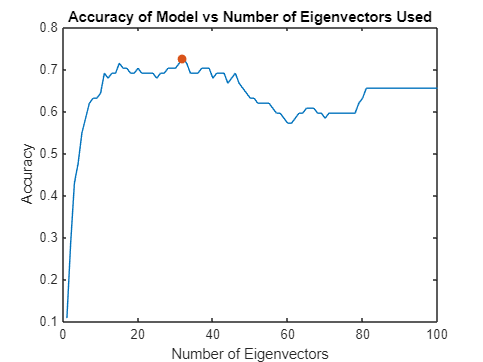

%plot accuracies
figure()
plot(accs)
hold on
[max_acc, max_eigs] = max(accs);
plot(max_eigs,max_acc,'.','MarkerSize',20)
xlabel("Number of Eigenvectors");
ylabel("Accuracy");
title("Accuracy of Model vs Number of Eigenvectors Used")

%test against real people
test_face_names = ["dexter", "mo", "glasses ian", "ollie"]

test_face_names = 1×4 string array
    "dexter"    "mo"    "glasses ian"    "ollie"


test_face_chars = zeros(length(test_face_names), 64*64);
for i = 1:length(test_face_names)
    test_face_chars(i,:) = double(reshape(rgb2gray(imread(test_face_names(i) + ".jpg")), [64*64, 1]));
end

Error using imread>get_full_filename
File "dexter.jpg" does not exist.

Error in imread (line 371)
    fullname = get_full_filename(filename);


%test img proj
test_idx = 4;
test_char = test_face_chars(test_idx, :);
test_proj = test_char * V;

%find test point with shortest distance from a train point
min_dist = 100000000;
min_dist_idx = 0;
for i = 1:length(train_names)
    temp_char_proj = char_proj(i,:);
    temp_dist = (test_proj - temp_char_proj).^2;
    temp_dist = sum(temp_dist);
    temp_dist = sqrt(temp_dist);
    if temp_dist < min_dist
        min_dist = temp_dist;
        min_dist_idx = i;
    end
end
figure()
colormap gray
imagesc(reshape(test_char, [64 64]))
test_face_names(test_idx)
imagesc(reshape(train_chars(min_dist_idx, :), [64 64]))
train_names(min_dist_idx)
